% ==========================================================
% Stability & Phase-Margin Analyzer (Reusable Template)
% ==========================================================
clear; clc

% --- USER INPUT ---
A0   = 1e4;           % DC open-loop gain
beta = 0.01;          % Feedback factor
wp1  = 2*pi*10;       % Dominant pole [rad/s]
wp2  = 2*pi*1e6;      % Non-dominant pole [rad/s]

% --- TRANSFER FUNCTION ---
s = tf('s');
A  = A0 / ((1 + s/wp1)*(1 + s/wp2));
L  = beta * A;

% --- MARGINS ---
[Gm,Pm,Wcg,Wcp] = margin(L);

% --- DISPLAY RESULTS ---
fprintf('Loop Gain βA0 = %.2f\n', beta*A0);

Loop Gain βA0 = 100.00


fprintf('Phase Margin  = %.1f°  at  ω = %.1f rad/s\n', Pm, Wcp);

Phase Margin  = 90.5°  at  ω = 6282.7 rad/s


fprintf('Gain Margin   = %.1f dB  at  ω = %.1f rad/s\n', 20*log10(Gm), Wcg);

Gain Margin   = Inf dB  at  ω = Inf rad/s


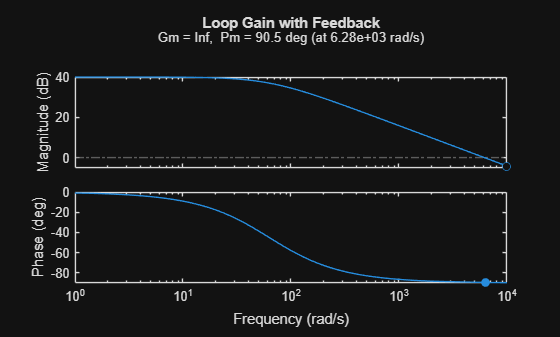


% --- BODE & NYQUIST ---
figure; margin(L); title('Loop Gain with Feedback');
exportgraphics(gcf, 'C:\Users\Mads2\DTU\Obsidian\Resources\Quiz8_BodeMargin.png', 'Resolution', 300);

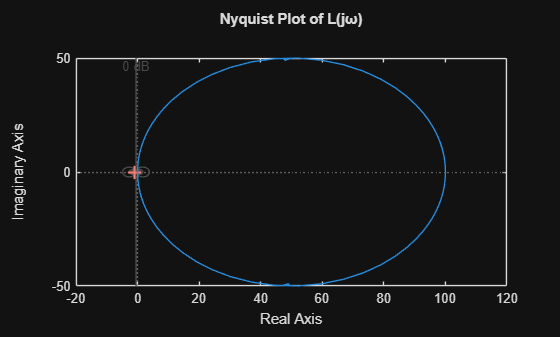


figure; nyquist(L); grid on; title('Nyquist Plot of L(jω)');
exportgraphics(gcf, 'C:\Users\Mads2\DTU\Obsidian\Resources\Quiz8_Nyquist.png', 'Resolution', 300);


% --- OPTIONAL: Damping Ratio & Peaking ---
zeta = sqrt(Pm/100);                % rough estimate
Mp   = exp(-pi*zeta/sqrt(1-zeta^2));
fprintf('Estimated Damping ζ = %.2f, Overshoot ≈ %.2f%%\n', zeta, 100*Mp);

Estimated Damping ζ = 0.95, Overshoot ≈ 0.01%


% ==========================================================